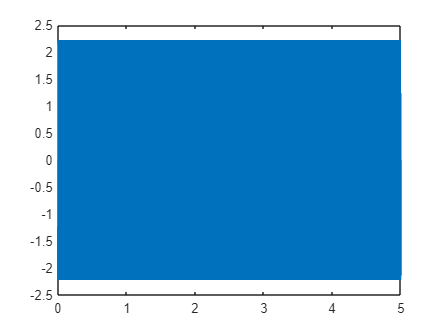

clear all
close all
clc

Te = 0.0001;
t = 0:Te:5;
f1 = 500;
f2 = 400;
f3 = 50;
% % signal en fct du temps
x = sin(2*pi*f1*t) + sin(2*pi*f2*t) + sin(2*pi*f3*t);
plot(t,x);

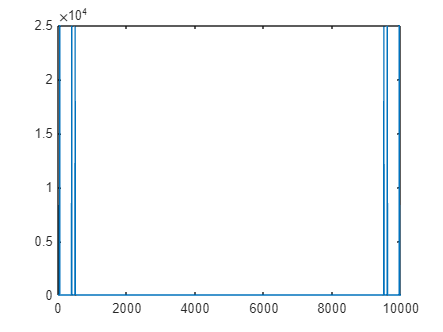


% fft du signal
X = fft(x);
f = (0:length(abs(X))-1)*(1/Te)/length(abs(X));


plot(f,abs(X));

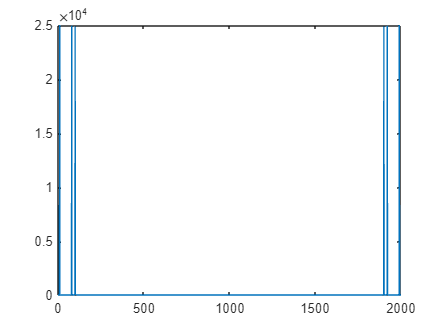


% pour Te=0.0005
Te2 = 0.0005;
f2 = (0:length(abs(X))-1)*(1/Te2)/length(abs(X));
plot(f2,abs(X));

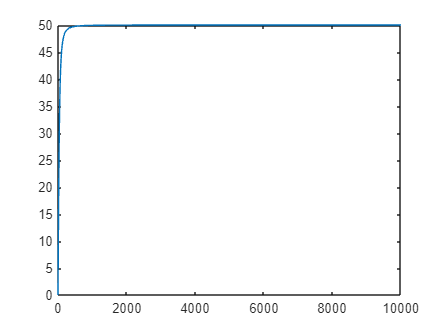


% transmittance complexe
wc = 50;
K = 1;
H = K*1i*f./(1 + 1i*f/wc);
plot(f,abs(H));

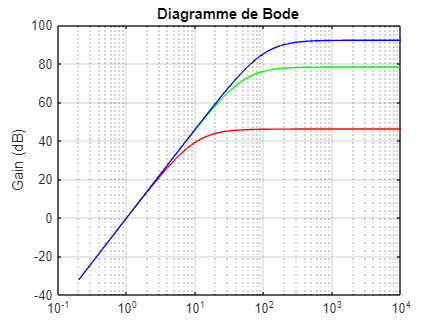


% 20.log(|H(f)|) pour différentes wc

wc1 = 10;
wc2 = 50;
wc3 = 100;

H1 = 1i*f./(1 + 1i*f/wc1);
H2 = 1i*f./(1 + 1i*f/wc2);
H3 = 1i*f./(1 + 1i*f/wc3);

H1_dB = 20*log(abs(H1));
H2_dB = 20*log(abs(H2));
H3_dB = 20*log(abs(H3));

ph1 = angle(H1);
ph2 = angle(H2);
ph3 = angle(H3);


semilogx(f,H1_dB, 'r', f, H2_dB, 'g', f, H3_dB, 'b');
ylabel('Gain (dB)');
title('Diagramme de Bode ');
grid on

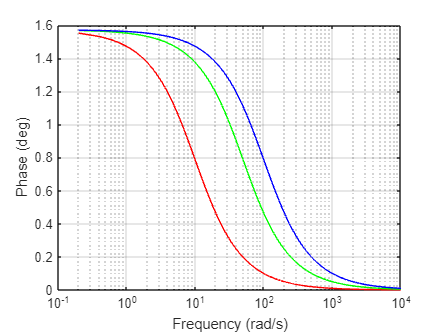


semilogx(f,ph1,  'r', f,ph2, 'g',f, ph3 ,'b');
xlabel('Frequency (rad/s)');
ylabel('Phase (deg)');

grid on

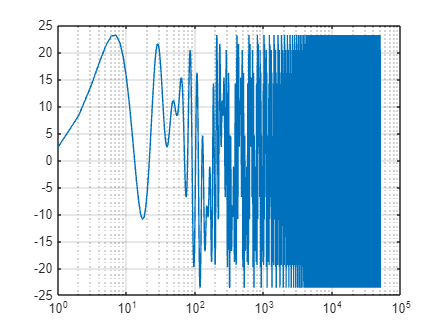


% % application du filtrage 
X_filtered1 = X.*H1;
X_filtered2 = X.*H2;
X_filtered3 = X.*H3;

x_filtered1 = ifft(X_filtered1,'symmetric');
x_filtered2 = ifft(X_filtered2,'symmetric');
x_filtered3 = ifft(X_filtered3,'symmetric');

semilogx(x_filtered1);
grid on

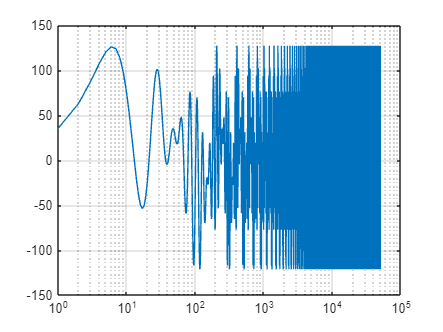


semilogx(x_filtered2);
grid on

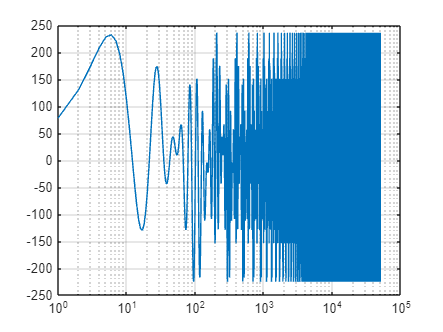


semilogx(x_filtered3);
grid on